clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);


Params = [
    "dMedian"
    "dIQR"
    "dMode"
    ];

Func = {
    @(x) median(x, 'omitnan');
    @iqr;
    @calMode;
    };


theta = strings(length(Params)*2, 1);
port = strings(length(Params)*2, 1);
theta_hat = zeros(length(Params)*2, 1);
ci_95 = zeros(length(Params)*2, 2);

for i = 1:length(Params) 
    
    n_boot = 1000;
    alpha_ci = 0.05;
    band_width = 0.12;

    cued_this = find(obj.CueUncue==0);

    for p = 1:length(obj.Ports)

        ind = 2*i+p-2;
        theta(ind) = Params(i);
        port(ind) = obj.Ports(p);

        data_control = obj.HDSortedControl{cued_this, p};
        data_chemo = obj.HDSortedChemo{cued_this, p};
        dParam_hat = Func{i}(data_chemo) - Func{i}(data_control);

        param_control_boot = bootstrp(n_boot, Func{i}, data_control);
        param_chemo_boot = bootstrp(n_boot, Func{i}, data_chemo);
        dParam_boot = param_chemo_boot - param_control_boot;
        dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

        theta_hat(ind) = dParam_hat;
        ci_95(ind, :) = dParam_boot_ci;
    end
    
end

StatTableHD = table(theta, port, theta_hat, ci_95);
head(StatTableHD)

      theta      port    theta_hat             ci_95         
    _________    ____    __________    ______________________

    "dMedian"    "L"        0.01875      -0.0041      0.03925
    "dMedian"    "R"       -0.04345      -0.0662      -0.0238
    "dIQR"       "L"       0.086175     0.040425      0.12009
    "dIQR"       "R"        0.08975     0.058113      0.12564
    "dMode"      "L"     -0.0083653    -0.079676    0.0037982
    "dMode"      "R"      -0.056994      -0.1361    -0.028827



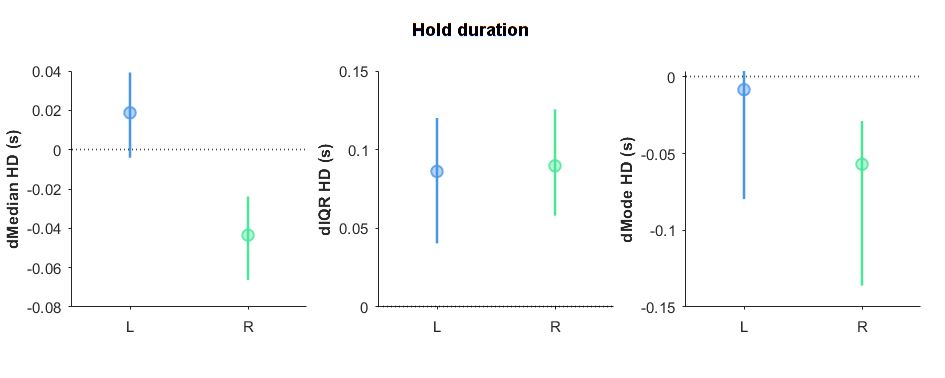

fig = figure(31); clf(31);
set(fig, 'Units', 'Centimeters', 'Position', [1 1 20 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig, 'units', 'normalized', 'position', [0.2 0.85 0.6 0.1],...
        'string', "Hold duration", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

x_pos = 1.5; y_pos = 1.5;
ax_size = [5 5];
for i = 1:length(Params) 

    ind = (1:2) + (i-1)*2;

    ax = axes();
    set(ax, 'Units', 'Centimeters', 'Position', [x_pos, y_pos ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');
    
    yline(ax, 0, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for p = 1:length(obj.Ports)
        scatter(ax, p, StatTableHD.theta_hat(ind(p)), 48, 'Marker', 'o', 'LineWidth', 1.2, ...
            'MarkerEdgeColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerEdgeAlpha', 0.8, ...
            'MarkerFaceColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerFaceAlpha', 0.4);
        plot(ax, [p p], StatTableHD.ci_95(ind(p), :), ...
            'Color', GPSColor.("Port"+obj.Ports(p)), 'LineWidth', 1.5);
    end
    set(ax, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["L", "R"]);
    ax.YLabel.String = Params(i) + " HD (s)";
    ax.YLabel.FontWeight = "bold";

    x_pos = x_pos + ax.Position(3) + 1.5;
end
save_name = "BootTest_HD_" + obj.Subject + "_" + obj.Task + ".png";
save_path = fullfile(ProgressClassFolder, save_name);
saveas(fig, save_path);


theta = strings(length(Params)*2, 1);
port = strings(length(Params)*2, 1);
theta_hat = zeros(length(Params)*2, 1);
ci_95 = zeros(length(Params)*2, 2);

for i = 1:length(Params) 
    
    n_boot = 1000;
    alpha_ci = 0.05;
    band_width = 0.12;

    cued_this = find(obj.CueUncue==0);

    for p = 1:length(obj.Ports)

        ind = 2*i+p-2;
        theta(ind) = Params(i);
        port(ind) = obj.Ports(p);

        data_control = obj.MTSortedControl{cued_this, p};
        data_chemo = obj.MTSortedChemo{cued_this, p};
        dParam_hat = Func{i}(data_chemo) - Func{i}(data_control);

        param_control_boot = bootstrp(n_boot, Func{i}, data_control);
        param_chemo_boot = bootstrp(n_boot, Func{i}, data_chemo);
        dParam_boot = param_chemo_boot - param_control_boot;
        dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

        theta_hat(ind) = dParam_hat;
        ci_95(ind, :) = dParam_boot_ci;
    end
    
end

StatTableMT = table(theta, port, theta_hat, ci_95);
head(StatTableMT)

      theta      port    theta_hat            ci_95         
    _________    ____    _________    ______________________

    "dMedian"    "L"        0.0614      0.04055       0.0778
    "dMedian"    "R"      -0.00015    -0.016475       0.0135
    "dIQR"       "L"      -0.10305     -0.18876    -0.055975
    "dIQR"       "R"      -0.10153     -0.13881    -0.064913
    "dMode"      "L"      0.081197     0.065661      0.11691
    "dMode"      "R"     0.0040043    -0.056024      0.02779



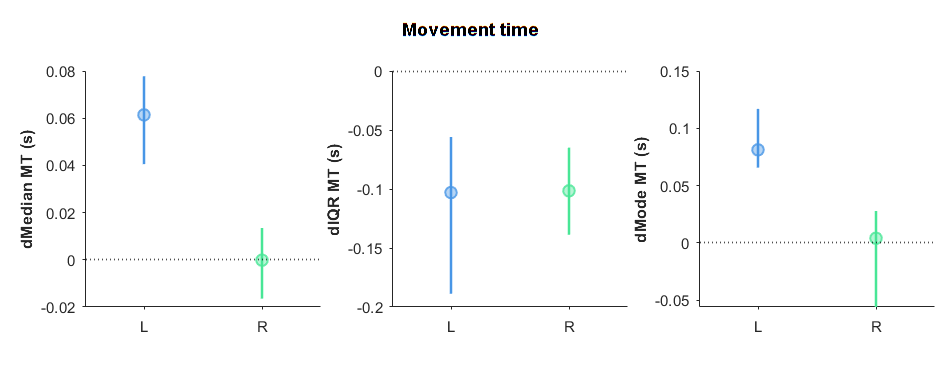

fig = figure(32); clf(32);
set(fig, 'Units', 'Centimeters', 'Position', [1 1 20 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig, 'units', 'normalized', 'position', [0.2 0.85 0.6 0.1],...
        'string', "Movement time", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

x_pos = 1.8; y_pos = 1.5;
ax_size = [5 5];
for i = 1:length(Params) 

    ind = (1:2) + (i-1)*2;

    ax = axes();
    set(ax, 'Units', 'Centimeters', 'Position', [x_pos, y_pos ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');
    
    yline(ax, 0, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for p = 1:length(obj.Ports)
        scatter(ax, p, StatTableMT.theta_hat(ind(p)), 48, 'Marker', 'o', 'LineWidth', 1.2, ...
            'MarkerEdgeColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerEdgeAlpha', 0.8, ...
            'MarkerFaceColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerFaceAlpha', 0.4);
        plot(ax, [p p], StatTableMT.ci_95(ind(p), :), ...
            'Color', GPSColor.("Port"+obj.Ports(p)), 'LineWidth', 1.5);
    end
    set(ax, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["L", "R"]);
    ax.YLabel.String = Params(i) + " MT (s)";
    ax.YLabel.FontWeight = "bold";

    x_pos = x_pos + ax.Position(3) + 1.5;
end
save_name = "BootTest_MT_" + obj.Subject + "_" + obj.Task + ".png";
save_path = fullfile(ProgressClassFolder, save_name);
saveas(fig, save_path);

theta = strings(length(Params)*2, 1);
port = strings(length(Params)*2, 1);
theta_hat = zeros(length(Params)*2, 1);
ci_95 = zeros(length(Params)*2, 2);

for i = 1:length(Params) 
    
    n_boot = 1000;
    alpha_ci = 0.05;
    band_width = 0.12;

    cued_this = find(obj.CueUncue==0);

    for p = 1:length(obj.Ports)

        ind = 2*i+p-2;
        theta(ind) = Params(i);
        port(ind) = obj.Ports(p);

        data_control = obj.HDSortedControl{cued_this, p};
        data_control = data_control(data_control>0.5);
        data_chemo = obj.HDSortedChemo{cued_this, p};
        data_chemo = data_chemo(data_chemo>0.5);
        dParam_hat = Func{i}(data_chemo) - Func{i}(data_control);

        param_control_boot = bootstrp(n_boot, Func{i}, data_control);
        param_chemo_boot = bootstrp(n_boot, Func{i}, data_chemo);
        dParam_boot = param_chemo_boot - param_control_boot;
        dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

        theta_hat(ind) = dParam_hat;
        ci_95(ind, :) = dParam_boot_ci;
    end
    
end

StatTableHDvalid = table(theta, port, theta_hat, ci_95);
head(StatTableHDvalid)

      theta      port    theta_hat             ci_95          
    _________    ____    _________    ________________________

    "dMedian"    "L"       0.02635      0.006525       0.05015
    "dMedian"    "R"       -0.0321      -0.05095      -0.00745
    "dIQR"       "L"        0.0773       0.03425       0.10795
    "dIQR"       "R"      0.070275      0.041488      0.099888
    "dMode"      "L"       0.02556    -0.0069444      0.079076
    "dMode"      "R"     -0.053342       -0.1275     -0.021308



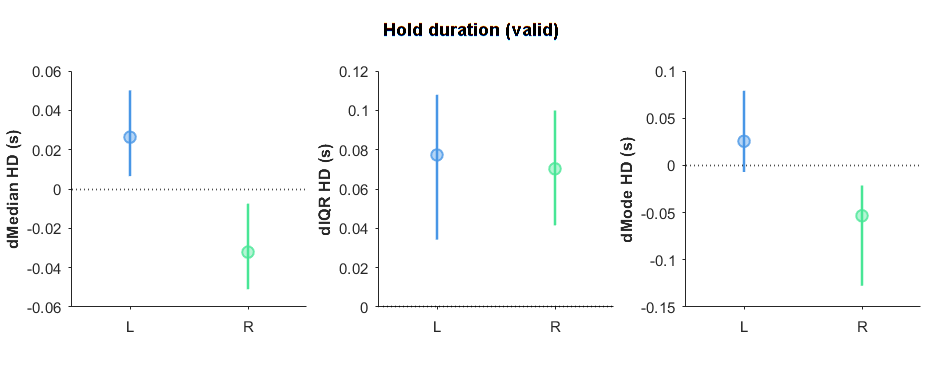

fig = figure(33); clf(33);
set(fig, 'Units', 'Centimeters', 'Position', [1 1 20 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig, 'units', 'normalized', 'position', [0.2 0.85 0.6 0.1],...
        'string', "Hold duration (valid)", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

x_pos = 1.5; y_pos = 1.5;
ax_size = [5 5];
for i = 1:length(Params) 

    ind = (1:2) + (i-1)*2;

    ax = axes();
    set(ax, 'Units', 'Centimeters', 'Position', [x_pos, y_pos ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');
    
    yline(ax, 0, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for p = 1:length(obj.Ports)
        scatter(ax, p, StatTableHDvalid.theta_hat(ind(p)), 48, 'Marker', 'o', 'LineWidth', 1.2, ...
            'MarkerEdgeColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerEdgeAlpha', 0.8, ...
            'MarkerFaceColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerFaceAlpha', 0.4);
        plot(ax, [p p], StatTableHDvalid.ci_95(ind(p), :), ...
            'Color', GPSColor.("Port"+obj.Ports(p)), 'LineWidth', 1.5);
    end
    set(ax, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["L", "R"]);
    ax.YLabel.String = Params(i) + " HD (s)";
    ax.YLabel.FontWeight = "bold";

    x_pos = x_pos + ax.Position(3) + 1.5;
end
save_name = "BootTest_HD_valid_" + obj.Subject + "_" + obj.Task + ".png";
save_path = fullfile(ProgressClassFolder, save_name);
saveas(fig, save_path);

function mode_this = calMode(x)

    [x_pdf, xi] = ksdensity(x);
    [~, id] = max(x_pdf);
    mode_this = xi(id);

end
